# **Semantic Segmentation - Galapagos Lavas**

## Setup and Labeling


%create datastore

clear all

home = false; %Set to true if working from home, false if working from school. 

%Set file paths for images to pixel label

if home
    addpath('F:\Research\Galapagos');
    filepath = ('F:\Research\Galapagos\Galapagos_imagery\Datastore');
else
    addpath (genpath('/home/johnpaustian/scratch/Imagery'));
    
    filepath = ('/home/johnpaustian/scratch/Imagery/Galapagos_imagery/Datastore');
end


imds = imageDatastore(filepath,'FileExtensions','.jpg');


%   Open Image Labeler to create pixel labels and save session. 
%   Comment out once labels and session are saved. 

% imageLabeler(imds)

%   labels are stored in 'galLabels.mat'
%   session is stored in 'galLabelingSession.mat'
    
load galLabels.mat labelDefs;
galLabels = labelDefs;

load galLabelingSession.mat imageLabelingSession;
galLabelingSession = imageLabelingSession.FileName;

## Image Labeler

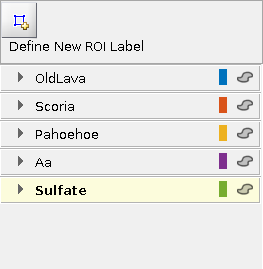

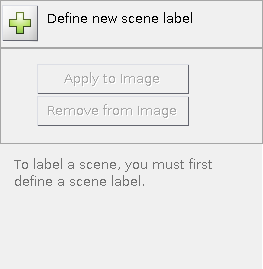

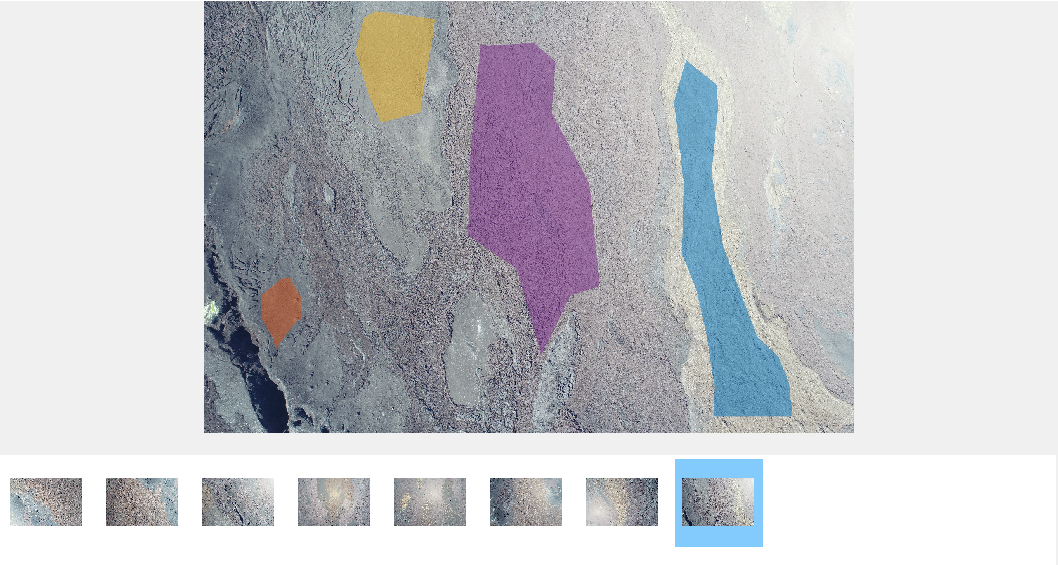

imageLabeler(galLabelingSession); %open image labeler, export ground truth

%Export ground truth from image labeler (gTruth.mat is output)

load gTruth.mat

%create pixel label datastore

pxds = pixelLabelDatastore(gTruth);

%create pixel label image datastore for training, resize images

pximds = pixelLabelImageDatastore(imds,pxds,'OutputSize',[100 150],'OutputSizeMode','resize');  %%%needs to be same number of files

%Training options

  %  solverName: sgdm stochastic gradient descent with momentum optimizer
  %  Momentum: contribution of previous step (0.9 is default)
  %  InitialLearnRate: 0.01 is default, lower generally increases accuracy/training time
  %  MaxEpochs: Epoch is full pass of training algorithm over full dataset
  %  VerboseFrequency: Frequency of verbose printing (number of iterations
  %                 between print to screen)
  %  MiniBatchSize: Batch for each training iteration. Used to evaluate
  %                 training loss

options = trainingOptions('sgdm','InitialLearnRate',1e-3, ...
    'MaxEpochs',100,'VerboseFrequency',10,...
    'ExecutionEnvironment','gpu','MiniBatchSize',256);

## Build Segmentation Network

% Set classes to names of lava classes
classes = galLabels{1:5,"Name"};

numClasses = numel(classes);

%Set network image input size
imageSize = [100 150 3]; 

%create lgraph object from SegNet layers (uninitalized encoder depth)
lgraph = segnetLayers(imageSize,numClasses,5);

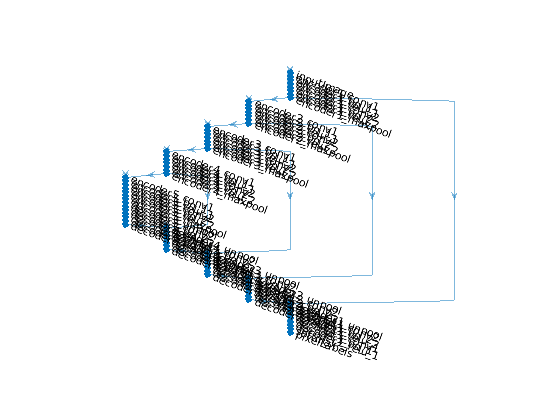

% Display segmentation network

plot(lgraph)

hAxes = gca; 
axis off

## Train Network

% Train neural network using pixel image datastore and pre-defined architecture

net = trainNetwork(pximds,lgraph,options)

Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:04 |       24.82% |       0.3826 |          0.0010 |
|      10 |          10 |       00:00:40 |       24.93% |       0.3751 |          0.0010 |
|      20 |          20 |       00:01:21 |       25.62% |       0.3654 |          0.0010 |
|      30 |          30 |       00:02:02 |       26.60% |       0.3599 |          0.0010 |
|      40 |          40 |       00:02:42 |       27.72% |       0.3549 |          0.0010 |
|      50 |          50 |       00:03:23 |       29.14% |       0.3501 |          0.0010 |
|      60 |          60 |       00:04:04 |       30

net =   DAGNetwork with properties:

         Layers: [73×1 nnet.cnn.layer.Layer]
    Connections: [82×2 table]


## Run trained network on test images

%create test imds

pxdsResults = semanticseg(testimds,net,'WriteLocation',tempdir);

## Evaluate Semantic Segmentation data set against ground truth

ssm = evaluateSemanticSegmentation(pxdsResults, pxdsTruth)

ssm.ClassMetrics

ssm.NormalizedConfusionMatrix